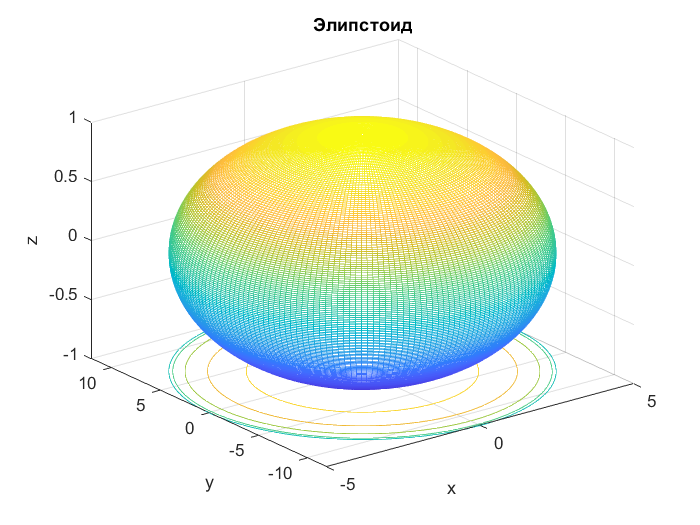

% 1) Поверхность второго порядка: эллипстоид 
% Уравнение: x^2/a^2 ++ y^2/b^2+z^2/с^2 =1 
%Задаем параметрически? 
rand_a = randi([1, 5], 1, 1);
rand_b = randi([10, 12], 1, 1);
rand_c = randi([1, 5], 1, 1);
theta=(-pi/2:pi/200:pi/2)'; %условие для того чтобы получить целый эллипстоид -pi/2 <= theta <= pi/2
phi=0:pi/100:2*pi; %То же условие, только для phi: 0 <= phi <= 2pi

x=rand_a*cos(theta)*cos(phi); %чтобы найти x необходимо

y=rand_b*cos(theta)*sin(phi); %для y

z=rand_c*sin(theta)*ones(size(phi)); %для z

figure ('Color','w')

meshc(x,y,z);

xlabel('x'), ylabel('y'),zlabel('z')
title("Эллипстоид")

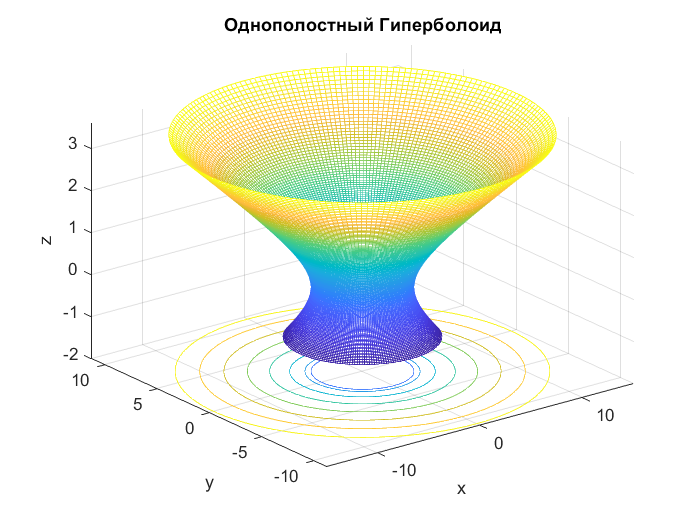

% Поверхность второго порядка: Однополоснтный Гиперболоид
% Задается уравнением: x^2/a^2 + y^2/b^2-z^2/c^2 = 1
% x = y = z (u; phi)
rand_G_a = randi([1, 4], 1, 1);
rand_G_b = randi([1, 4], 1, 1);
rand_G_c = randi([1, 1], 1, 1);
u = (-1:0.02:2)';
phi=0:0.01*pi:2*pi;
X = rand_G_a*cosh(u)*cos(phi);
Y = rand_G_b*cosh(u)*sin(phi);
Z = rand_G_c*sinh(u)*ones(size(phi));
figure('Color', 'w')
%mesh(X,Y,Z); 
meshc(X, Y, Z);
xlabel('x'),ylabel('y'),zlabel('z');
title('Однополостный Гиперболоид')

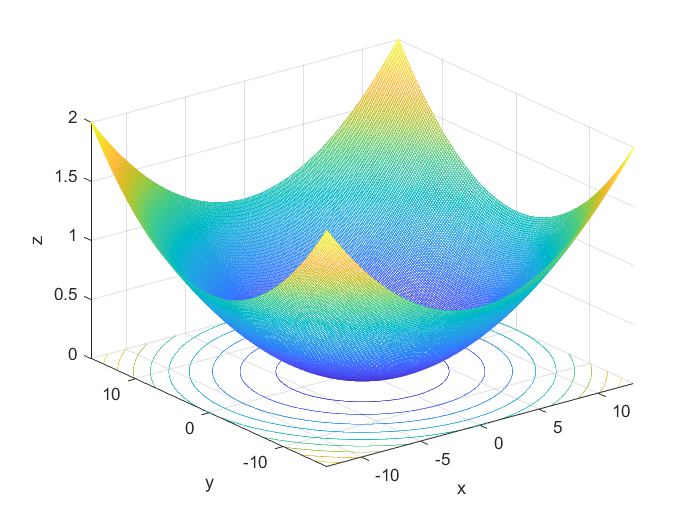

%camlight('right')так некрасиво, поэтому нет 
%Поверхность второго порядка: Эллиптический параболоид
%Задается уравнением: x^2/a^2+y^2/b^2-z
Rand_A = randi([10, 20], 1, 1);
Rand_B = randi([10, 20], 1, 1);
[X_g, Y_g] = meshgrid(-Rand_A:0.1:Rand_A, -Rand_B:0.2:Rand_B);
Z_g = (X_g.^2/Rand_A^2 + Y_g.^2/Rand_B^2);
figure('Color','w')
meshc(X_g, Y_g, Z_g);
xlabel('x'),ylabel('y'),zlabel('z')
title('')

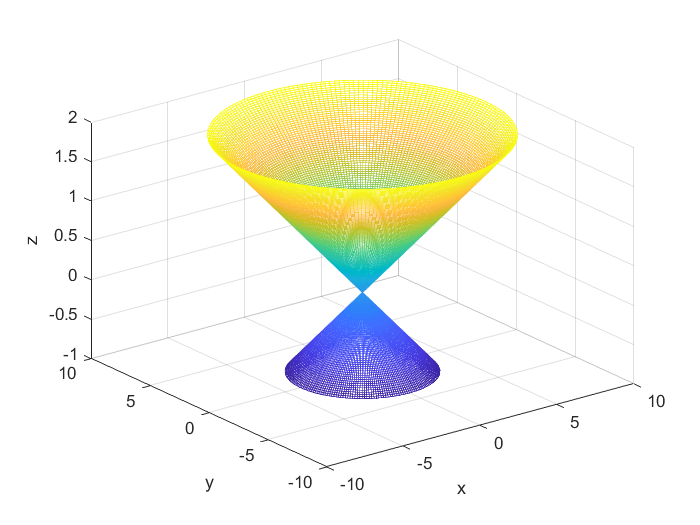

rand_K_a = randi([1, 4], 1, 1);
rand_K_b = randi([1, 4], 1, 1);
rand_K_c = randi([1, 1], 1, 1);
u = (-1:0.02:2)';
phi=0:0.01*pi:2*pi;
X_K = rand_K_a*u*cos(phi);
Y_K = rand_K_b*u*sin(phi);
Z_K = rand_K_c*u*ones(size(phi));
figure('Color', 'w')
%mesh(X,Y,Z); 
mesh(X_K, Y_K, Z_K);
xlabel('x'),ylabel('y'),zlabel('z');